clear
clf 

simTimEnd=100;
samplingTime=0.01;

% Generating intial condition:
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x1=a+(b-a)*rand();
x2=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=1; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
        u1(index,:)=sin(2*i);
        u2(index,:)=sin(i); 

    %The contious time model: 
    x1dot=0.1*x2(index,1)+0.5*u1(index,:);
    x2dot=-0.8*x1(index,1)+0.1*x2(index,1)+0.5*u2(index,:);
    
   %Using forward euler to get the states value: 
    index=index+1; 
    x1(index,1)=x1dot*samplingTime+x1(index-1,1);
    x2(index,1)=x2dot*samplingTime+x2(index-1,1);
end

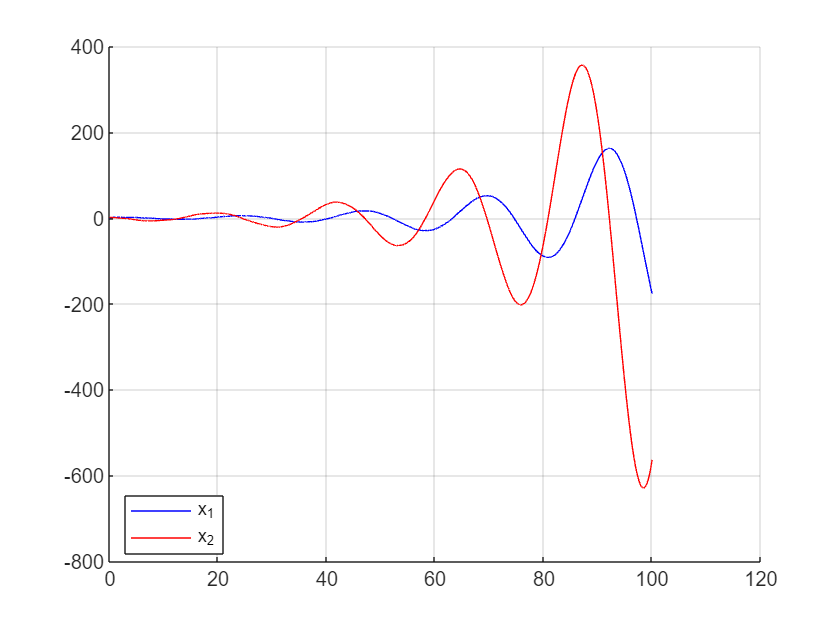

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 
clf
hold on 
plot(time,x1,'blue')
plot(time,x2,'red')
hold off 
grid
legend('x_1','x_2','location','best')


%Laver Xk og Xk+1
Xk(1,:)=x1(1:5000,1)';
Xk(2,:)=x2(1:5000,1)';

Xk1(1,:)=x1(2:5001,1)';
Xk1(2,:)=x2(2:5001,1)';

%Samle ens input series: 
Uk(1,:)=u1(1:5000,1)';
Uk(2,:)=u2(1:5000,1)';

% [U,S,V]=svd(Xk1);

%Laver omega
Omega=[Xk;Uk]; 
%Tager SVD af Omega:
[U,S,V]=svd(Omega); 

trun=4;
Ut=U(:,1:trun);
St=S(1:trun,1:trun); 
Vt=V(:,1:trun); 


%Bestemmer A og B: 
G=Xk1*Vt*inv(St)*transpose(U); 


A=G(1:2,1:2); 
B=G(1:2,3:4); 



%LAver one step prediction fra 5001

%Samler x og u i en matrix: 
x=[x1';x2'];
input=[u1';u2']; 


index=1; 
for i=5001:size(x1,1)-1
    xP(:,index)=A*x(:,i)+B*input(:,i); 
 index=index+1;
end 

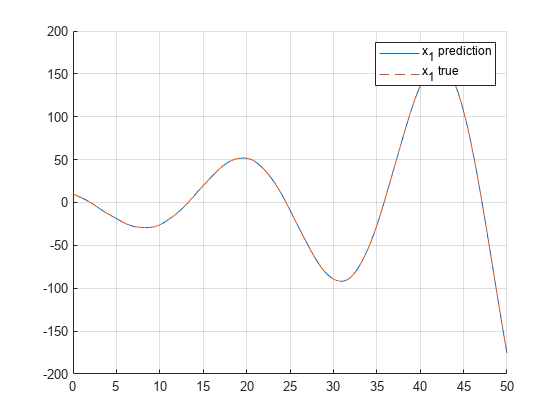


time2=0:samplingTime:50;

 clf 
figure(2)
hold on 
plot(time2,x1(5002:end,1))
plot(time2,xP(1,:),'--')
hold off
legend('x_1 prediction','x_1 true')
ax=gca;

grid 
exportgraphics(ax,"x1_DMDc.pdf")

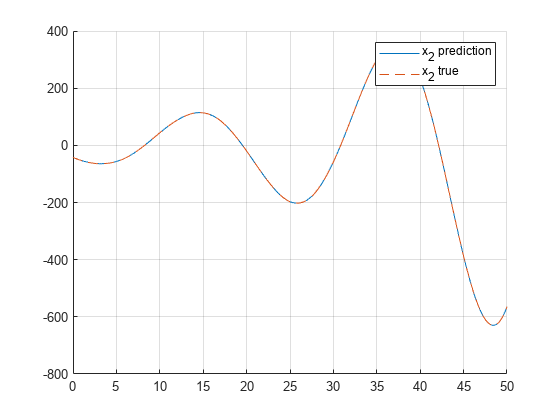


ax=gca;

clf
figure(3)
hold on 
plot(time2,x2(5002:end,1))
plot(time2,xP(2,:),'--')

hold off
legend('x_2 prediction','x_2 true')
grid 

ax=gca;
exportgraphics(ax,"x2_DMDc.pdf")


%Det ser jo rigtigt fint ud, prøver at lave det samme med en nonlinear
%model 